clear, clc
[q_ddot, q, u, vars] = robot_arm_dynamics();
[A,B,dq,du] = linearize_around_state(q_ddot,q,u);

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1         arm1         jnt1     revolute             base(0)   arm2(2)  
   2         arm2         jnt2     revolute             arm1(1)   arm3(3)  
   3         arm3         jnt3        fixed             arm2(2)   
--------------------


ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


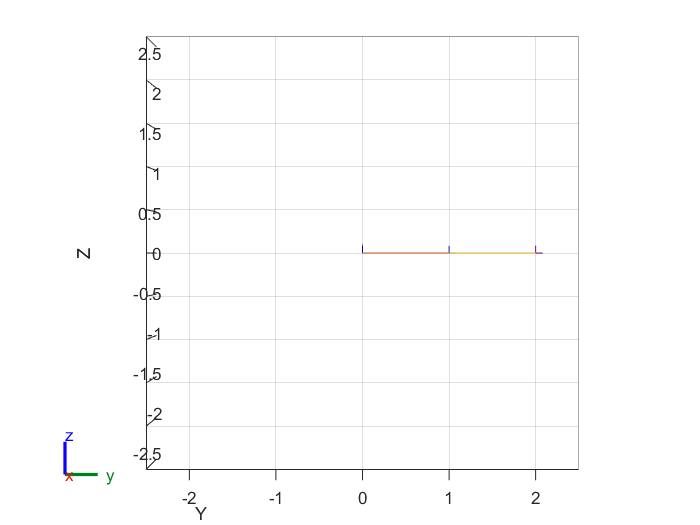

% Create robot
robot = create_robot_tree(1);

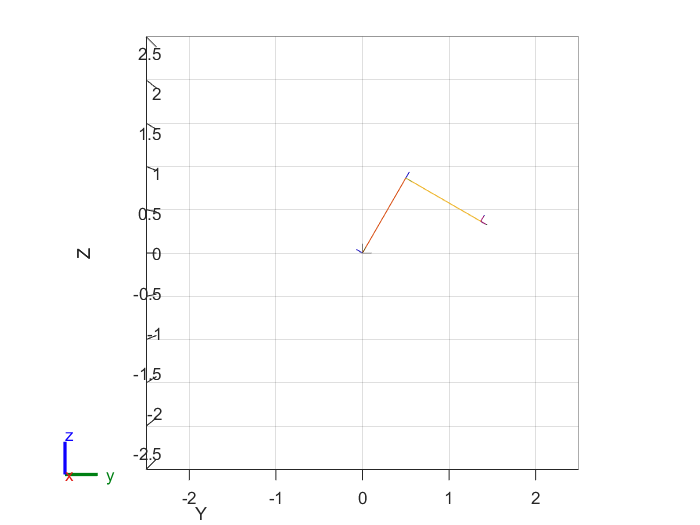

% robot.Gravity = [0 0 -9.81];
config = homeConfiguration(robot);
pose = [pi/3; -pi/2];
show(robot,pose);
xlim([-.01,.01])
view(90,0)

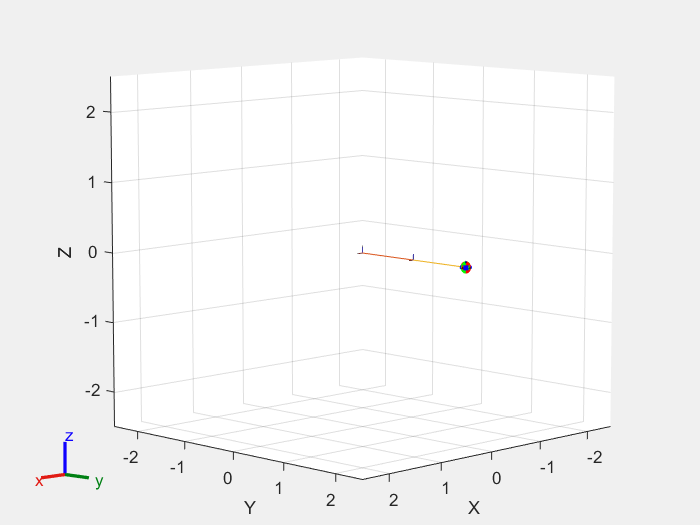

gui = interactiveRigidBodyTree(robot,"MarkerScaleFactor",0.25);

% Create trajectory
ik = inverseKinematics('RigidBodyTree',robot)

ik =   inverseKinematics with properties:

       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


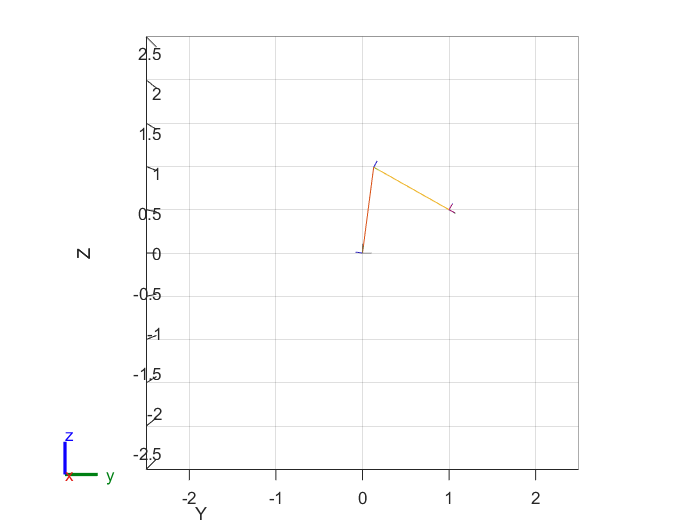

% ignore orientation for now
weights = [0 0 0 1 1 1];

% Get joint pos. of initial pose
tform1 = trvec2tform([0 1 0.5]);
[soln1,solnInfo1] = ik("arm3",tform1,weights,pose);
% show(robot,soln1);
% xlim([-.01,.01])
% view(90,0)

% joint pos. of final pose
tform2 = trvec2tform([0 -1 1]);
[soln2,solnInfo2] = ik("arm3",tform2,weights,pose);

wpts = [soln1 soln2];
tpts = [0 3];
r = 0.1;
tvec = 0:r:3;
count = length(tvec);
[q, qd, qdd, pp] = cubicpolytraj(wpts, tpts, tvec);

show(robot,soln1);
xlim([-.01,.01])
view(90,0)

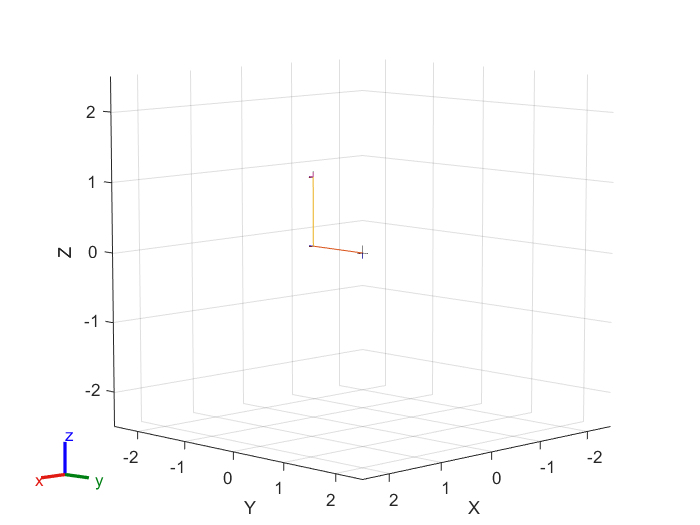

for i = 1:count
    show(robot,q(:,i),'PreservePlot',false);
    drawnow
    waitfor(r);
end